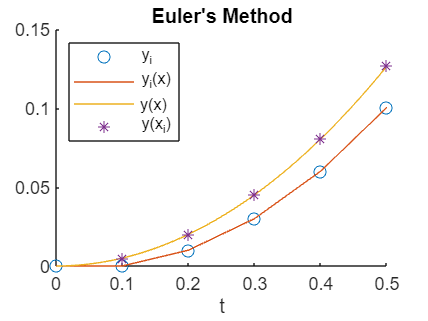

f = @(x,y) x + y^2;
n = 5;
x0 = 0;
xn = 0.5;
y0 = 0;
[y,x] = Euler(f,n,x0,xn,y0);

syms t
y_z = dsolve("Dy == t+y^2","y(0)=0");
y_x = double(subs(y_z,t,x));
error = double(abs(y_x-y));
x_i = x';
y_i = y';
z_i = y_x';
Error = error';
%table(x_i,y_i,z_i,Error)
scatter(x,y);
hold on 
plot(x,y)
ezplot(y_z,[x0,xn]);
scatter(x,y_x,'*');
xlim auto
ylim auto
title("Euler's Method");
lgd = legend("y_i","y_i(x)","y(x)","y(x_i)");
lgd.Location="northwest";
hold off

f = @(x,y) [-y(2);y(1)]

f = function_handle with value:
    @(x,y)[-y(2);y(1)]


n=5;
x0=0;
xn=0.5

xn = 0.5000

y0=[-1;1];
syms t
[y1sol,y2sol] = dsolve("Dy1 == -y2","Dy2 == y1","y1(0)=-1","y2(0)=1")

$$y1sol = -\cos\left(t\right)-\sin\left(t\right)$$

$$y2sol = \cos\left(t\right)-\sin\left(t\right)$$

[y,x] = Euler(f,n,x0,xn,y0)

y =    -1.0000   -1.1000   -1.1900   -1.2690   -1.3361   -1.3905
    1.0000    0.9000    0.7900    0.6710    0.5441    0.4105


x =          0    0.1000    0.2000    0.3000    0.4000    0.5000


y1sol_x = double(subs(y1sol,t,x));
y2sol_x = double(subs(y2sol,t,x));
x_i=x';
Y_i=y';
for i = 1:n
    error(:,i) = norm(e1(1,i)-e2(1-i),"inf");
Error = error';
Y_x_i=[y1sol_x;y2sol_x]';
table(x_i,Y_i,Y_x_i,Error);
E = norm(error,"inf");
scater(x,y)
hold on
plot(x,y);
ezplot(y1sol,[x0,xn]);
ezplot(y2sol,[x0,xn]);
scatter(x,y1sol_x,"*");
scatter(x,y2sol_x,"*");
xlim auto
ylim auto
lgd=legend("y1_i","y2_i","y1_i(x)","y2_i(x)","y1(x)","y2(x)","y1(x_i)","y2(x_i)");
title("Euler's Method for system of ODE's");